# Using simulink to visualise car suspension behaviour

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours. However, the real world is full of more complex components and connections. In such cases writing code can be messy or difficult and it is often easier to capture the scenario using tools such as simulink.

This livescript is a brief introduction to the use of simulink to model and simulate a simple suspension systems. More importantly, it shows how integration with MATLAB code can make running the simulink file very efficient to allow systematic investigations for a range of parameter values. This livescript file makes use of the following simulink file:

- carsuspension_control101.slx 

For more generic and comprehensive help on and introduction to Simulink, use the Mathworks onramp website.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Preamble

Many simulink files have a large number of parameters which are most conveniently defined with a supporting MATLAB script and thus one might as well run the simulink file directly from the same script and produce neat plots rather than using scopes. For convenience, this resource uses options which **import and export data to the main MATLAB workspace** so the values can be used elsewhere as needed, for example in plotting.

For more generic and comprehensive help on and introduction to Simulink, use the Mathworks onramp website.

## 1. Simple car suspension model

We consider a car suspension and displacement can be represented as a combination of simple mass-spring-damper models, as follows:


$$Y_1 =G_{\textrm{y1}} Y_2 ;\;\;\;\;Y_2 =G_{\textrm{y2}} Y_1 +G_z Z$$


$G_{\textrm{y1}} =\frac{\frac{b}{M}s+\frac{k_1 }{M}}{s^2 +\frac{b}{M}s+\frac{k_1 }{M}}$;     $G_{\textrm{y2}} =\frac{s+\frac{k_2 }{b}}{s+\frac{k_1 +k_2 }{b}}$;  $G_z =\frac{\frac{k_2 }{b}}{s+\frac{k_1 +k_2 }{b}}$;  

 with *Z* the road profile,  $Y_1$ the mass/car chassis displacement, $Y_2$ the wheel centre displacement, $k_1 ,b$ the supension spring and damping and $k_2$ representing the tyre stiffness. 

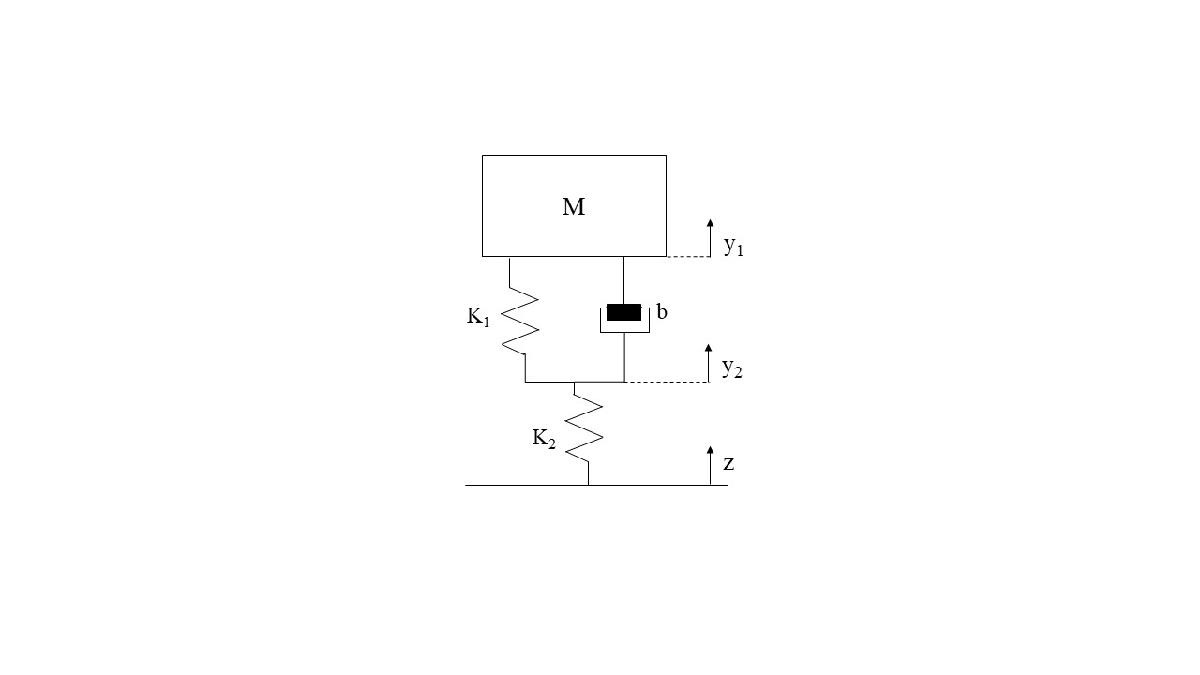

**Figure 1.1**: Schematic of car suspension.

This system of equations can be represented in simulink using the following block diagram. Open the simulink file to investigate more carefully and/or to make changes.

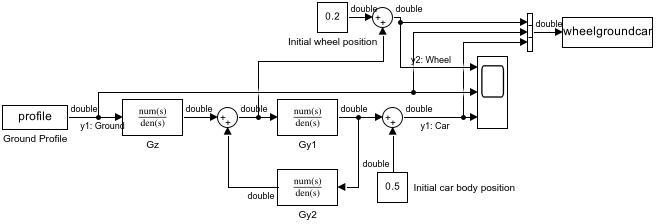

**Figure 1.2**: Screen capture of*** car_suspension_control101.slx***

## 2. Simulation of the suspension system model

We need to define all the required parameters before running the simulink file. This includes:

- Component values.

- Initial conditions.

- Road profile.

The values can be defined through a MATLAB script (see code below), after which we can run the simulink model and determine the behaviours. The values are collected for plotting in MATLAB, but a scope is also illustrated in this code so that, once the parameters are defined in the workspace, one could run the simulation directly from the simulink window if desired.

### 2.1 Nominal simulation

disp('*****************************')

*****************************


disp('Section 2.1 illustrations below')

Section 2.1 illustrations below



% open car_suspension_control101.slx  % to open simulink file

% Define parameters needed by simulink file
M=500;     % Mass
k1=7500;   % Spring constant
k2=170000; % Sprng constant
b=1250;    % damping
v=10;      % velocity
clear l %l=2;       % 
h=0.3;     % step size
t_stop=6;   % simulation end time
ramp = 0:.02:1;
time=[0;1;1+5*ramp'/v;5]; % time profile
ground=[0;0;ramp'*h;h];            % ground profile
profile = [time,ground];     % time and ground profiles overlaid

% Simulation
sim("car_suspension_control101.slx");
% Output data is in the structure wheelgroundcar
wheelgroundcar

wheelgroundcar = struct with fields:
         time: [262×1 double]
      signals: [1×1 struct]
    blockName: 'car_suspension_control101/To Workspace'


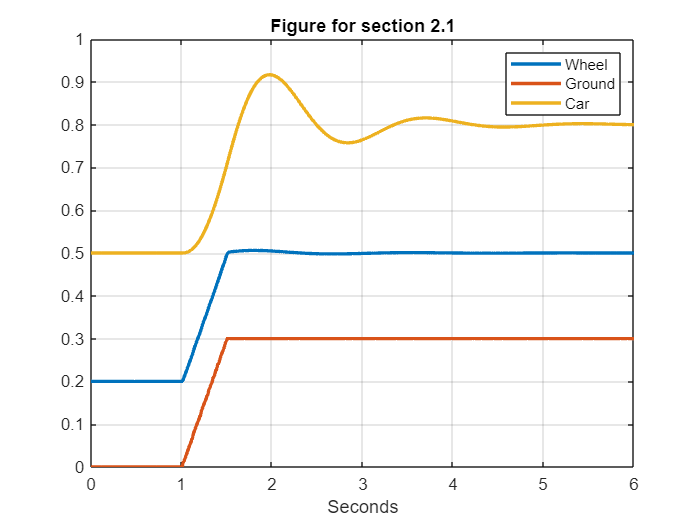



% Plotting
figure
plot(wheelgroundcar.time,wheelgroundcar.signals.values,'LineWidth',2)
grid
legend('Wheel','Ground','Car')
title('Figure for section 2.1')
xlabel('Seconds')


Task1 = wheelgroundcar; % save output for later section

%print(['-scar_suspension_control101'],'-djpeg',['car_suspension_control101.jpg'])



### 2.2 What is the impact of changing speed?

The code here simply changes the velocity and variables that depend on that such as timing and profile dependence on time.

disp('*****************************')

*****************************


disp('Section 2.2 illustrations below')

Section 2.2 illustrations below


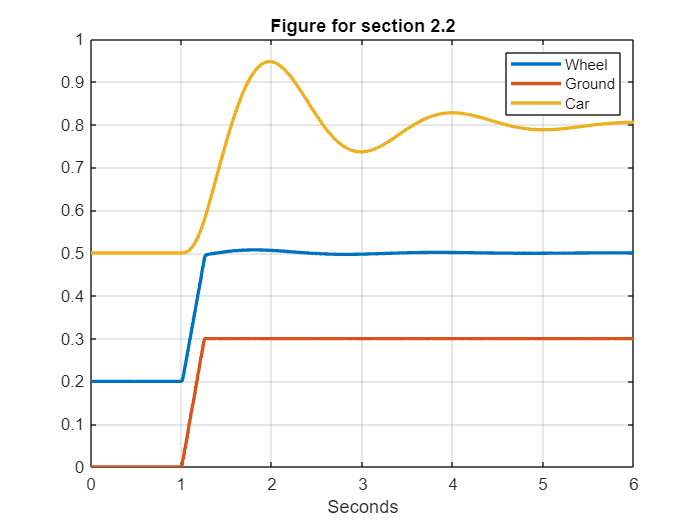


% Values same as section 2.1
M=700; k1=7500;k2=170000;b=1250;h=0.3;t_stop=6;ramp = 0:.02:1;

% Changed values
v=20;
time=[0;1;1+5*ramp'/v;5]; % time profile
ground=[0;0;ramp'*h;h]; 
profile = [time,ground]; % time and ground profiles overlaid

% Simulation
sim("car_suspension_control101.slx");
% Data is in the structure wheelgroundcar

% Plotting
figure
plot(wheelgroundcar.time,wheelgroundcar.signals.values,'LineWidth',2)
grid
legend('Wheel','Ground','Car')
title('Figure for section 2.2')
xlabel('Seconds')


Task2 = wheelgroundcar; % save output for later section

## 2.3. Improving the suspension design

This section modifies the values of the suspension to reduce the oscillation. 

disp('*****************************')

*****************************


disp('Section 2.3 illustrations below')

Section 2.3 illustrations below


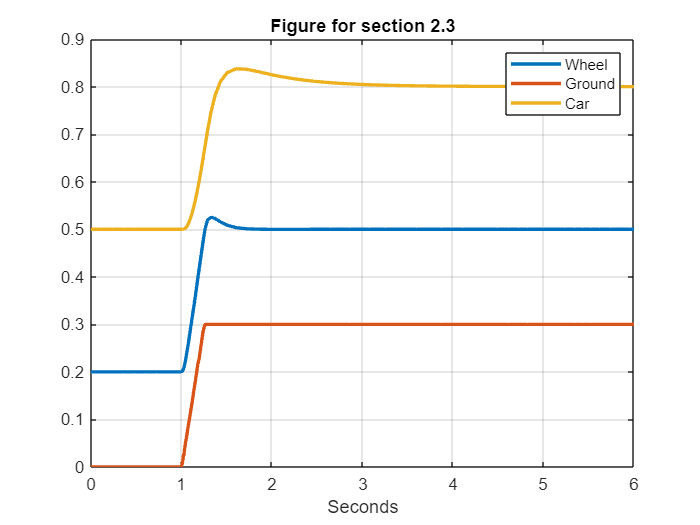


% Unchanged values compared to section 2.2
M=700; k1=7500; k2=170000; v=20; h=0.3;
ramp = 0:.02:1;
t_stop=6;
time=[0;1;1+5*ramp'/v;5]; % time profile
ground=[0;0;ramp'*h;h]; 
profile = [time,ground]; % time and ground profiles overlaid

% Changed values
b=5500;

% Simulation
sim("car_suspension_control101.slx");
% Data is in the structure wheelgroundcar

% Plotting
figure
plot(wheelgroundcar.time,wheelgroundcar.signals.values,'LineWidth',2)
grid
legend('Wheel','Ground','Car')
title('Figure for section 2.3')
xlabel('Seconds')


Task3 = wheelgroundcar; % save output for later section

### 2.4.  Collect and compare results from all 3 simulations

it is interesting to overlay plots so we can see how changes in damping and speed affect the behaviour. This section will only run once the previous ones have been run to generate the required data.

disp('*****************************')

*****************************


disp('Section 2.4 illustrations below')

Section 2.4 illustrations below


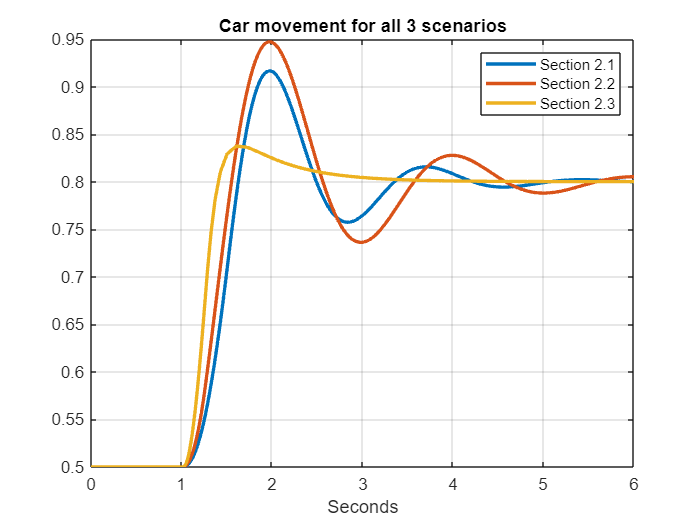

figure
plot(Task1.time,Task1.signals.values(:,3),'LineWidth',2); hold on
plot(Task2.time,Task2.signals.values(:,3),'LineWidth',2); hold on
plot(Task3.time,Task3.signals.values(:,3),'LineWidth',2); hold on
grid
legend('Section 2.1','Section 2.2','Section 2.3')
title('Car movement for all 3 scenarios')
xlabel('Seconds')